# RGB Image rotation by rotation matrix

[[source]](https://stackoverflow.com/a/19687481/13182960)

## 1. read image

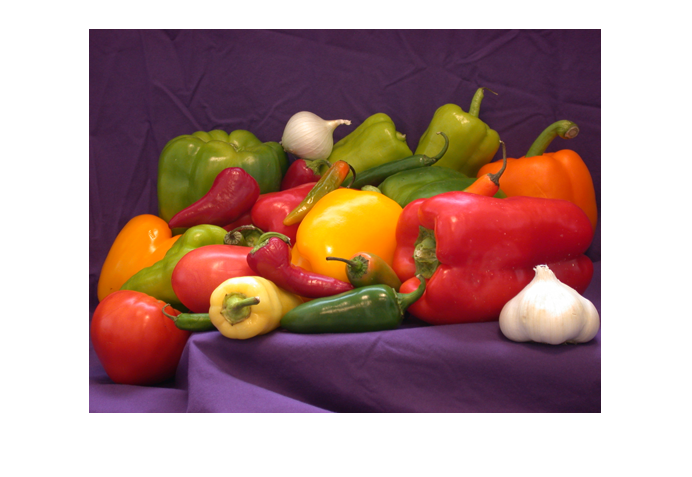

image = imread('peppers.png');
imshow(image)

## 2. apply rotation matrix to pixel locations

Mr = [cos(pi/4) sin(pi/4); -sin(pi/4) cos(pi/4)]; % e.g. 45 degree CCW

[nrows, ncols, nslices] = size(image);
midx=ceil((ncols+1)/2);
midy=ceil((nrows+1)/2);
% rotate about center
[X, Y] = meshgrid(1:ncols,1:nrows);
XYt = [X(:)-midx Y(:)-midy];
XYt = XYt*Mr;
XYt = bsxfun(@plus,XYt,[midx midy]);

## 3. Approximate new pixel locations to their nearest neighbor (lossy for color)

xout = round(XYt(:,1)); yout = round(XYt(:,2)); % nearest neighbor!
outbound = yout<1 | yout>nrows | xout<1 | xout>ncols; %mark pixels to be cropped
xout(xout<1) = 1; xout(xout>ncols) = ncols;
yout(yout<1) = 1; yout(yout>nrows) = nrows;

## 4. look up pixel values from original image

This is done efficiently by converting subscripts of rotated coordinates to index imposed by the original image

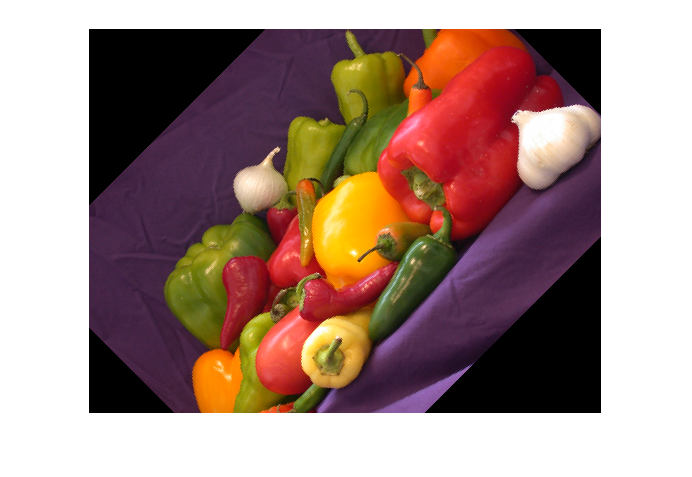

xout = repmat(xout,[3 1]); 
yout = repmat(yout,[3 1]); 
zout=repmat(cat(3,1,2,3),nrows,ncols,1);    %cat(3,1,2,3) puts 1,2,3 vector in 3rd dimension
zout=zout(:); 
imagerot = image(sub2ind(size(image),yout,xout,zout(:))); 
imagerot = reshape(imagerot,size(image));
imagerot(repmat(outbound,[1 1 3])) = 0; % set background value to [0 0 0] (black)
imshow(imagerot);